# Degradation Curves

Use this file to

- view the curves

- accelerate them

- alter them

- save them

load Q_degradation.csv
load R0_degradation.csv
% motor deg is derived below

## Plot the curves

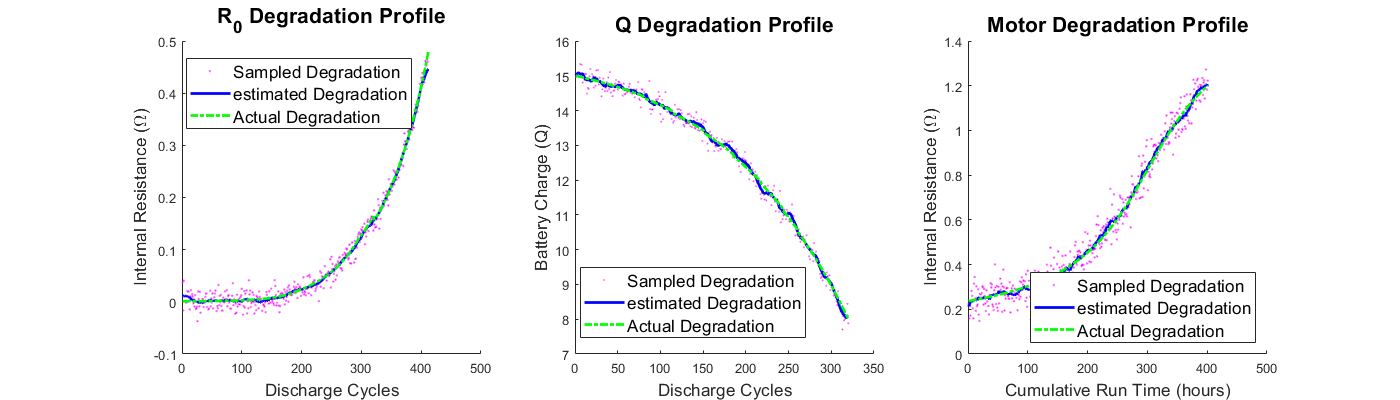

rdeg = interp1([R0_degradation(1) R0_degradation(end)], [.0011 0.48], R0_degradation);
rdegr = normrnd(rdeg, .013);
restr = movmean(rdegr, 22);

frdeg = figure("Name", "rdeg"); clf;
frdeg.Position = [0 0 1400 400];
subplot(1,3,1);
hold on;
plot(rdegr, 'm.', 'markersize', 3, "DisplayName", "Sampled Degradation");
plot(restr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(rdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Internal Resistance (\Omega)",  'fontsize', 13);
title("R_0 Degradation Profile", 'fontsize', 16);
legend('location', 'best',  'fontsize', 13);


qdeg = interp1([Q_degradation(1) Q_degradation(end)], [15 8], Q_degradation);
qdegr = normrnd(qdeg, .2);
qestr = movmean(qdegr, 10);
subplot(1,3,2);
% fqdeg = figure("Name", "qdeg"); clf;
% fqdeg.Position = [0 0 800 400];
hold on;
plot(qdegr, 'm.', 'markersize', 1, "DisplayName", "Sampled Degradation");
plot(qestr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(qdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Battery Charge (Q)",  'fontsize', 13);
title("Q Degradation Profile", 'fontsize', 16);
legend('Location', 'best',  'fontsize', 13);
x = -15:.05:05;
y = atan(x/5)/7;
mdeg = interp1([y(1) y(end)], [.2371 1.2], y);
mdegr = normrnd(mdeg, .05);
mestr = movmean(mdegr, 15);
% fmdeg = figure("Name", "mdeg"); clf;
% fmdeg.Position = [0 0 800 400];
subplot(1,3,3);
hold on;
plot(mdegr, 'm.', 'markersize', 3, "DisplayName", "Sampled Degradation");
plot(mestr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(mdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Cumulative Run Time (hours)", 'fontsize', 13);
ylabel("Internal Resistance (\Omega)", 'fontsize', 13);
title("Motor Degradation Profile", 'fontsize', 16);
legend('location', 'southeast', 'fontsize', 13);

## Save the curves

save('params\rdeg.mat', 'rdeg');
save('params\qdeg.mat', 'qdeg');
save('params\mdeg.mat', 'mdeg');

## Downsample the curve

- accelerated degradation only!

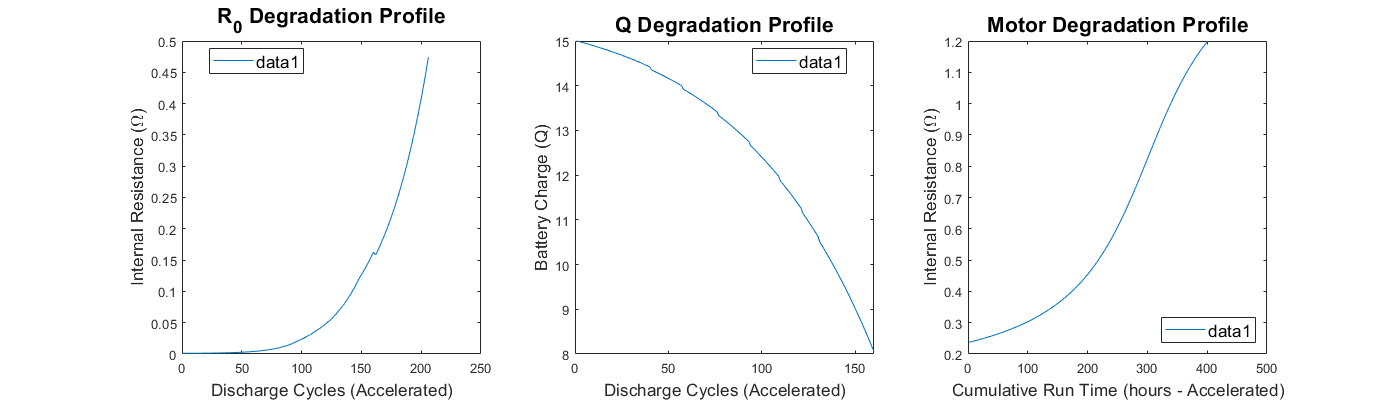

rdown = downsample(rdeg, 2);
qdown = downsample(qdeg, 2);
%mdown = downsample(mdeg, 2)';
%rdown = rdeg;
mdown = mdeg';

f2 = figure(2); clf;
f2.Position = [0 0 1200 300];
subplot(1,3,1);
plot(rdown);
xlabel("Discharge Cycles (Accelerated)",  'fontsize', 13);
ylabel("Internal Resistance (\Omega)",  'fontsize', 13);
title("R_0 Degradation Profile", 'fontsize', 16);
legend('location', 'best',  'fontsize', 13);
subplot(1,3,2);
plot(qdown);
xlabel("Discharge Cycles (Accelerated)",  'fontsize', 13);
ylabel("Battery Charge (Q)",  'fontsize', 13);
title("Q Degradation Profile", 'fontsize', 16);
legend('Location', 'best',  'fontsize', 13);
subplot(1,3,3);
plot(mdown);
xlabel("Cumulative Run Time (hours - Accelerated)", 'fontsize', 13);
ylabel("Internal Resistance (\Omega)", 'fontsize', 13);
title("Motor Degradation Profile", 'fontsize', 16);
legend('location', 'southeast', 'fontsize', 13);

## Save the accelerated curves

rdeg = rdown(:);
qdeg = qdown(:);
mdeg = mdown(:);
save('params\rdeg.mat', 'rdeg');
save('params\qdeg.mat', 'qdeg');
save('params\mdeg.mat', 'mdeg');

save('params\rdown.mat', 'rdown');
save('params\qdown.mat', 'qdown');
save('params\mdown.mat', 'mdown');

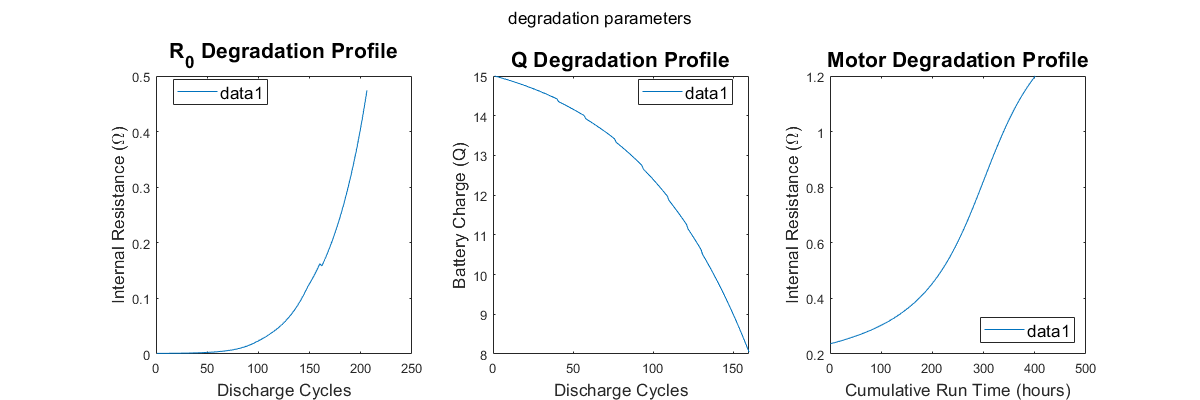

f3 = figure("name", "deg"); clf;
f3.Position = [0 0 1200 400];
subplot(1,3,1);
plot(rdeg);
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Internal Resistance (\Omega)",  'fontsize', 13);
title("R_0 Degradation Profile", 'fontsize', 16);
legend('location', 'best',  'fontsize', 13);

subplot(1,3,2);
plot(qdeg);
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Battery Charge (Q)",  'fontsize', 13);
title("Q Degradation Profile", 'fontsize', 16);
legend('Location', 'best',  'fontsize', 13);

subplot(1,3,3);
plot(mdeg);
xlabel("Cumulative Run Time (hours)", 'fontsize', 13);
ylabel("Internal Resistance (\Omega)", 'fontsize', 13);
title("Motor Degradation Profile", 'fontsize', 16);
legend('location', 'southeast', 'fontsize', 13);
sgtitle('degradation parameters');

Have we defined where failure is for each component?